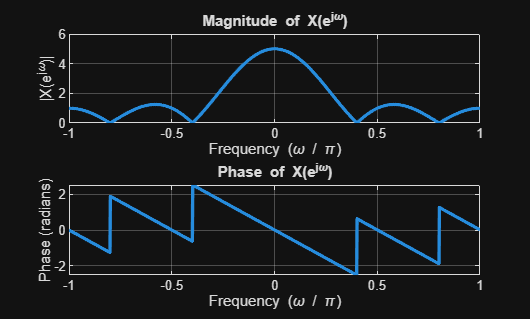

% Define the signal x[n]
% x[n] = u[n] - u[n-5] which means 1s at indices 0,1,2,3,4
x = [1, 1, 1, 1, 1]; 
N = length(x);

% Define the frequency vector for high resolution
% 1024 points from -pi to pi
[H, w] = freqz(x, 1, 1024, 'whole'); 

% freqz by default returns 0 to 2pi. 
% We want to shift it to be -pi to pi to match standard textbook sketches.
H = fftshift(H);
w = w - 2*pi; % Shift range to roughly -2pi to 0
w = w + pi;   % Correction to center at 0 (manual adjustment often cleaner)
% A cleaner way to generate the w axis manually for plotting:
w = linspace(-pi, pi, 1024);

% --- Plotting Magnitude ---
figure;
subplot(2,1,1);
plot(w/pi, abs(H), 'LineWidth', 2);
title('Magnitude of X(e^{j\omega})');
xlabel('Frequency (\omega / \pi)');
ylabel('|X(e^{j\omega})|');
grid on;
xlim([-1 1]); 
% Check for the peak at 5 and zeros at 0.4, 0.8

% --- Plotting Phase ---
subplot(2,1,2);
% Unwrap removes the artificial 2pi jumps to show the linear trend
theta = angle(H); 
plot(w/pi, theta, 'LineWidth', 2);
title('Phase of X(e^{j\omega})');
xlabel('Frequency (\omega / \pi)');
ylabel('Phase (radians)');
grid on;
xlim([-1 1]);